# Taller 1, puntos 11 y 12: Adaline sobre las particiones de banknote

El punto 11 pide las mismas particiones del punto 5, asi que se cargan las que dejo T3_dataset_banknote. El punto 12 es repetir el 10 con ellas.

clear; close all; clc
load banknote_splits.mat
if ~exist('informe/figuras', 'dir'), mkdir('informe/figuras'); end
if ~exist('informe/tablas', 'dir'),  mkdir('informe/tablas');  end

## Parametros

op.umbral     = 0.5;
op.salida     = [0 1];
op.error_min  = 1e-3;
op.max_epocas = 500;
op.semilla    = 1;
alphas = [0.0001 0.001 0.005 0.01 0.05];

## Entrenamiento con y sin escalar

Aqui el escalado importa mas que en el perceptron, porque con la regla delta una entrada grande como la curtosis (llega a 17) hace que el error se dispare si alpha no es muy chico.

filas = {};
for escalar = [false true]
    for k = 1:numel(S)
        Xtr = S(k).Xtr;  Xte = S(k).Xte;
        dtr = S(k).ytr;  dte = S(k).yte;
        if escalar
            mn = min(Xtr); mx = max(Xtr);
            Xtr = (Xtr - mn) ./ (mx - mn);
            Xte = (Xte - mn) ./ (mx - mn);
        end
        for a = alphas
            o = op; o.alpha = a;
            [w, b, info] = adaline(Xtr, dtr, o);
            acc_tr = mean(predecir(Xtr, w, b, o.umbral, o.salida) == dtr);
            acc_te = mean(predecir(Xte, w, b, o.umbral, o.salida) == dte);
            etiqueta = sprintf('%d-%d', round(100*S(k).p), round(100*(1-S(k).p)));
            filas(end+1, :) = {escalar, etiqueta, a, info.epocas, info.ec_final, ...
                               100*acc_tr, 100*acc_te}; %#ok<SAGROW>
        end
    end
end
R = cell2table(filas, 'VariableNames', ...
    {'Escalado', 'Particion', 'Alpha', 'Epocas', 'EC_final', 'Exact_train', 'Exact_test'});
disp(R)

    Escalado    Particion    Alpha     Epocas    EC_final    Exact_train    Exact_test
    ________    _________    ______    ______    ________    ___________    __________

     false      {'60-40'}    0.0001     225       13.177       97.934         96.721  
     false      {'60-40'}     0.001      41       13.938       98.056          97.45  
     false      {'60-40'}     0.005      11       18.925        97.57         96.539  
     false      {'60-40'}      0.01       6       39.003       95.383         93.989  
     false      {'60-40'}      0.05       2          Inf       37.181         36.066  
     false      {'70-30'}    0.0001     199       15.203       98.021         96.117  
     false      {'70-30'}     0.001      36       16.079       98.542         96.359  
     false      {'70-30'}     0.005      10       21.961        98.75         97.087  
     false      {'70-30'}      0.01       6       46.772       98.333          97.33  
     false      {'70-30'}      0.05       

writetable(R, 'informe/tablas/ada_banknote.csv');

## Resumen

Res = groupsummary(R, {'Escalado', 'Particion'}, 'mean', {'Epocas', 'Exact_train', 'Exact_test'});
disp(Res)

    Escalado    Particion    GroupCount    mean_Epocas    mean_Exact_train    mean_Exact_test
    ________    _________    __________    ___________    ________________    _______________

     false      {'60-40'}        5               57            85.225             84.153     
     false      {'70-30'}        5             50.6            87.625             86.262     
     false      {'80-20'}        5               45            83.206             83.577     
     false      {'90-10'}        5             40.8            89.895             89.197     
     true       {'60-40'}        5              340            95.601             95.046     
     true       {'70-30'}        5            316.2            96.146                 95     
     true       {'80-20'}        5            297.4            96.047             96.423     
     true       {'90-10'}        5              292            95.968             95.766     



## Grafica

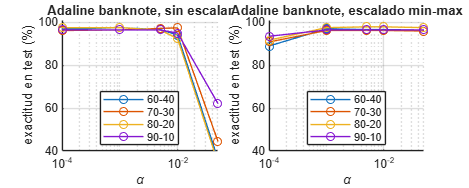

figure('Position', [100 100 950 380]);
titulos = {'sin escalar', 'escalado min-max'};
for e = 1:2
    subplot(1, 2, e); hold on
    for k = 1:numel(S)
        etiqueta = sprintf('%d-%d', round(100*S(k).p), round(100*(1-S(k).p)));
        m = R.Escalado == (e == 2) & strcmp(R.Particion, etiqueta);
        plot(R.Alpha(m), R.Exact_test(m), '-o', 'DisplayName', etiqueta);
    end
    set(gca, 'XScale', 'log'); grid on; ylim([40 101]);
    xlabel('\alpha'); ylabel('exactitud en test (%)'); title(['Adaline banknote, ' titulos{e}]);
    legend('Location', 'best');
end
guardar_fig('ada_banknote');

## Curva de error del mejor caso y su matriz de confusion

[~, imax] = max(R.Exact_test);
fprintf('Mejor caso: escalado=%d, particion %s, alpha=%g, exactitud test %.2f%%\n', ...
    R.Escalado(imax), R.Particion{imax}, R.Alpha(imax), R.Exact_test(imax));

Mejor caso: escalado=1, particion 80-20, alpha=0.005, exactitud test 97.81%


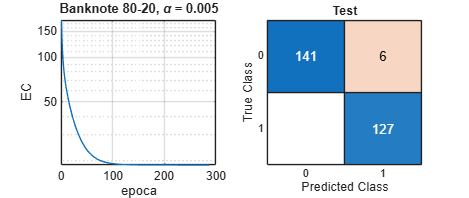

k = find(strcmp(cellfun(@(p) sprintf('%d-%d', round(100*p), round(100*(1-p))), {S.p}, 'UniformOutput', false), R.Particion{imax}));
Xtr = S(k).Xtr; Xte = S(k).Xte;
if R.Escalado(imax)
    mn = min(Xtr); mx = max(Xtr);
    Xtr = (Xtr - mn) ./ (mx - mn);  Xte = (Xte - mn) ./ (mx - mn);
end
o = op; o.alpha = R.Alpha(imax);
[w, b, info] = adaline(Xtr, S(k).ytr, o);
figure('Position', [100 100 900 380]);
subplot(1,2,1); semilogy(info.ec_por_epoca); grid on
xlabel('epoca'); ylabel('EC'); title(sprintf('Banknote %s, \\alpha = %g', R.Particion{imax}, o.alpha));
subplot(1,2,2); confusionchart(S(k).yte, predecir(Xte, w, b, o.umbral, o.salida));
title('Test');
guardar_fig('ada_banknote_mejor');

## Perceptron contra Adaline en banknote, particion 80-20 escalada

Para cerrar: los dos modelos sobre el mismo dataset, mismo alpha.

Xtr = S(3).Xtr; Xte = S(3).Xte;
mn = min(Xtr); mx = max(Xtr);
Xtr = (Xtr - mn) ./ (mx - mn);  Xte = (Xte - mn) ./ (mx - mn);
filas = {};
for a = [0.001 0.01 0.05 0.1]
    op_p = struct('regla', 3, 'alpha', a, 'umbral', 0.5, 'salida', [0 1], 'max_epocas', 500, 'semilla', 1);
    [wp, bp, ip] = perceptron(Xtr, S(3).ytr, op_p);
    op_a = op; op_a.alpha = a;
    [wa, ba, ia] = adaline(Xtr, S(3).ytr, op_a);
    filas(end+1, :) = {a, ip.epocas, 100*mean(predecir(Xte, wp, bp, 0.5, [0 1]) == S(3).yte), ...
                       ia.epocas, 100*mean(predecir(Xte, wa, ba, 0.5, [0 1]) == S(3).yte)}; %#ok<SAGROW>
end
R2 = cell2table(filas, 'VariableNames', {'Alpha', 'Epocas_perc', 'Exact_test_perc', 'Epocas_ada', 'Exact_test_ada'});
disp(R2)

    Alpha    Epocas_perc    Exact_test_perc    Epocas_ada    Exact_test_ada
    _____    ___________    _______________    __________    ______________

    0.001        500            98.905            500            97.445    
     0.01        500            98.905            154             97.81    
     0.05        500            98.905             46            97.445    
      0.1        500            97.445             26            97.445    



writetable(R2, 'informe/tablas/perc_vs_ada_banknote.csv');